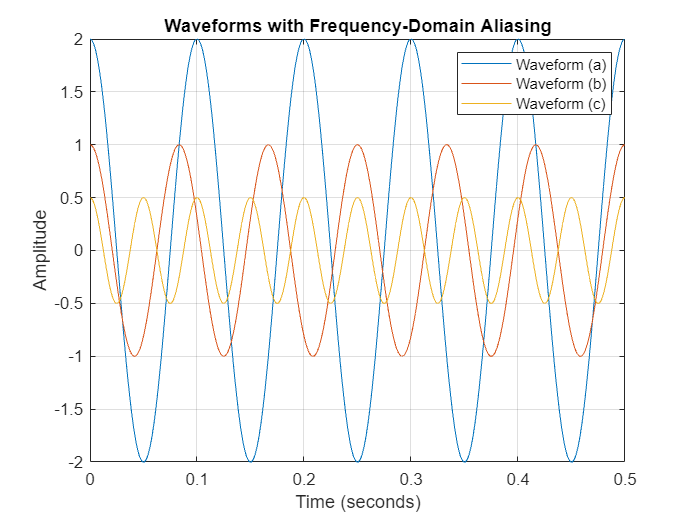

alpha = 2;
duration = 1/alpha;

t = [0:0.0001:duration];

% Waveform (a): Cosine function with amplitude alpha and frequency 5alpha Hz
waveform_a = alpha * cos(2 * pi * 5 * alpha * t);

% Waveform (b): Cosine function with amplitude alpha/2 and frequency 6alpha Hz
waveform_b = (alpha/2) * cos(2 * pi * 6 * alpha * t);

% Waveform (c): Cosine function with amplitude alpha/4 and frequency 10alpha Hz
waveform_c = (alpha/4) * cos(2 * pi * 10 * alpha * t);

figure;
plot(t, waveform_a, 'DisplayName', 'Waveform (a)');
hold on;
plot(t, waveform_b, 'DisplayName', 'Waveform (b)');
plot(t, waveform_c, 'DisplayName', 'Waveform (c)');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Waveforms with Frequency-Domain Aliasing');
legend;
grid on;
hold off;

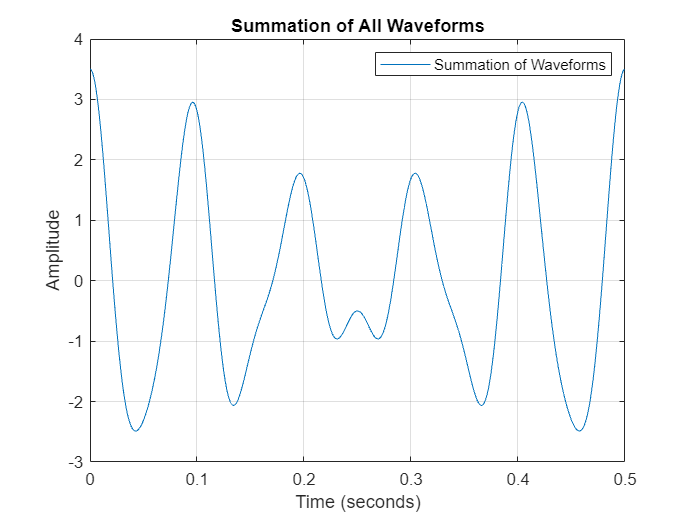

alpha = 2;
duration = 1/alpha;
t = [0:0.0001:duration];

% Waveform (a): Cosine function with amplitude alpha and frequency 5alpha Hz
waveform_a = alpha * cos(2 * pi * 5 * alpha * t);

% Waveform (b): Cosine function with amplitude alpha/2 and frequency 6alpha Hz
waveform_b = (alpha/2) * cos(2 * pi * 6 * alpha * t);

% Waveform (c): Cosine function with amplitude alpha/4 and frequency 10alpha Hz
waveform_c = (alpha/4) * cos(2 * pi * 10 * alpha * t);

% Summation of all waveforms
summation = waveform_a + waveform_b + waveform_c;

figure;
plot(t, summation, 'DisplayName', 'Summation of Waveforms');
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Summation of All Waveforms');
legend;
grid on;

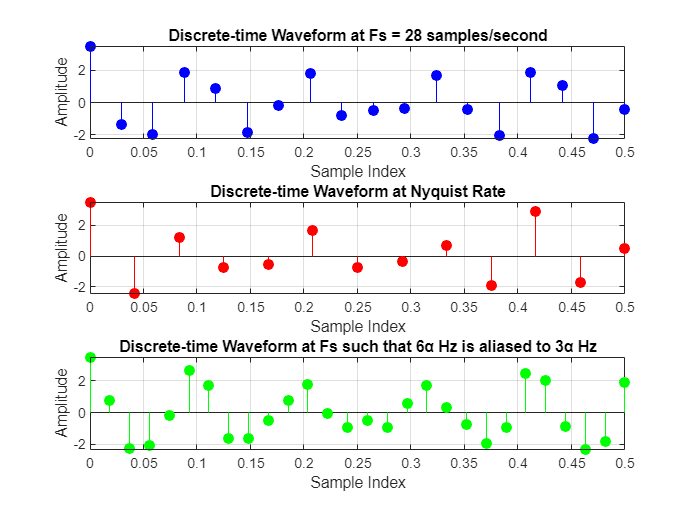

Fs_a = 14 * alpha;
Fs_b = 2 * frequency_c; % Nyquist rate
Fs_c = 9 * alpha; % Aliasing

% Sample the cumulative signal at different sampling frequencies
samples_a = sum_waveform(1 : round(Fs_a) : end);
samples_b = sum_waveform(1 : round(Fs_b) : end);
samples_c = sum_waveform(1 : round(Fs_c) : end);

% Discrete-time waveforms using stem
time_a = linspace(0, duration, length(samples_a));
time_b = linspace(0, duration, length(samples_b));
time_c = linspace(0, duration, length(samples_c));


% Create the discrete-time waveforms plot
figure;

subplot(3, 1, 1);
stem(time_a, samples_a, 'b', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title(['Discrete-time Waveform at Fs = ', num2str(Fs_a), ' samples/second']);
grid on;

subplot(3, 1, 2);
stem(time_b, samples_b, 'r', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Discrete-time Waveform at Nyquist Rate');
grid on;

subplot(3, 1, 3);
stem(time_c, samples_c, 'g', 'filled');
xlabel('Sample Index');
ylabel('Amplitude');
title('Discrete-time Waveform at Fs such that 6α Hz is aliased to 3α Hz');
grid on;

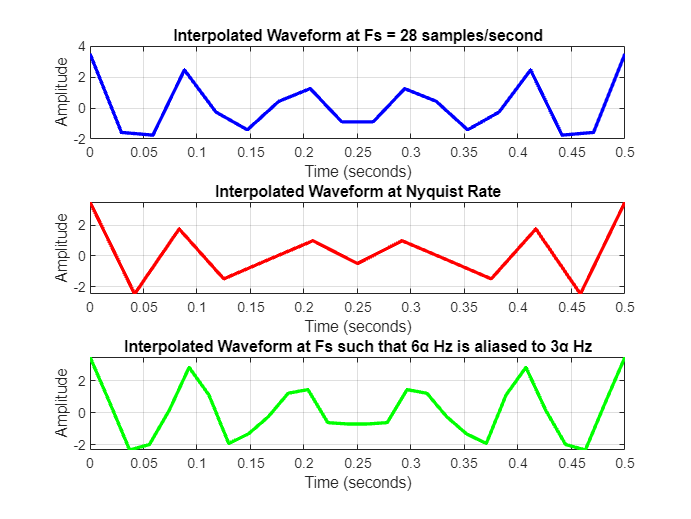

interp_time_a = linspace(0, duration, length(samples_a));
interp_waveform_a = interp1(time, sum_waveform, interp_time_a, 'linear');

interp_time_b = linspace(0, duration, length(samples_b));
interp_waveform_b = interp1(time, sum_waveform, interp_time_b, 'linear');

interp_time_c = linspace(0, duration, length(samples_c));
interp_waveform_c = interp1(time, sum_waveform, interp_time_c, 'linear');

% Plot the interpolated waveforms
figure;

subplot(3, 1, 1);
plot(interp_time_a, interp_waveform_a, 'b', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(['Interpolated Waveform at Fs = ', num2str(Fs_a), ' samples/second']);
grid on;

subplot(3, 1, 2);
plot(interp_time_b, interp_waveform_b, 'r', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Interpolated Waveform at Nyquist Rate');
grid on;

subplot(3, 1, 3);
plot(interp_time_c, interp_waveform_c, 'g', 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(['Interpolated Waveform at Fs such that 6α Hz is aliased to 3α Hz']);
grid on;

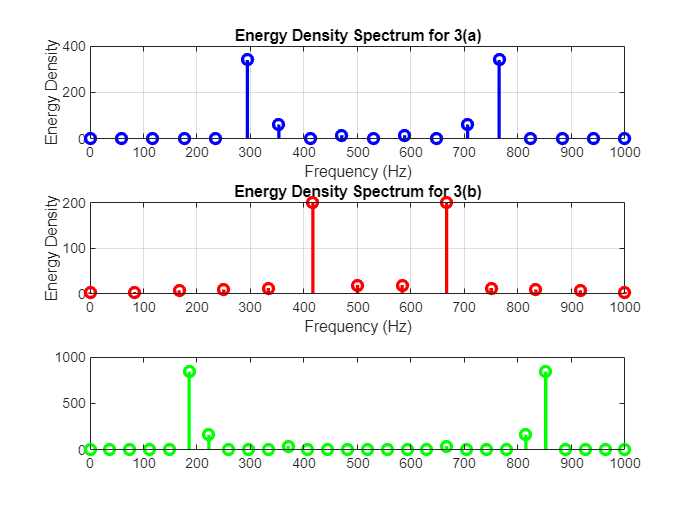

fft_a = fft(samples_a);
fft_b = fft(samples_b);
fft_c = fft(samples_c);

% Frequency values
freq_a = linspace(0, sampling_rate, length(fft_a));
freq_b = linspace(0, sampling_rate, length(fft_b));
freq_c = linspace(0, sampling_rate, length(fft_c));

% Plot the energy density spectrum
figure;

subplot(3, 1, 1);
stem(freq_a, abs(fft_a).^2, 'b', 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Energy Density');
title('Energy Density Spectrum for 3(a)');
grid on;

subplot(3, 1, 2);
stem(freq_b, abs(fft_b).^2, 'r', 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('Energy Density');
title('Energy Density Spectrum for 3(b)');
grid on;

subplot(3, 1, 3);
stem(freq_c, abs(fft_c).^2, 'g', 'LineWidth', 2);